Defining the path.

addpath('code')

Setting up the system.

Defining variables.

% connection.
host='localhost';
port=3000;

% data.
datapoint_size=328;
bytearrayread='';
t_idx=1;
datapoint_byte=[];
numberpoints=1280;
numberchans=40;

% data cleaning.
windowsize=20;
outlcoef=5;
movingavwindow=3;




Initialize Client to begin receiving data

% initialize Client.
% create object Eneeb_client.
client=Eneeb_client(host, port);
client.create();

[CLIENT: ] Retry 1 connecting to localhost:3000
[CLIENT: ] Retry 2 connecting to localhost:3000
[CLIENT: ] Retry 3 connecting to localhost:3000
[CLIENT: ] Retry 4 connecting to localhost:3000
[CLIENT: ] Retry 5 connecting to localhost:3000
[CLIENT: ] Retry 6 connecting to localhost:3000
[CLIENT: ] Retry 7 connecting to localhost:3000
[CLIENT: ] Retry 8 connecting to localhost:3000
[CLIENT: ] Retry 9 connecting to localhost:3000
[CLIENT: ] Connected to server



% start clock.
t1=tic;

Once the connection is established, check for new data.

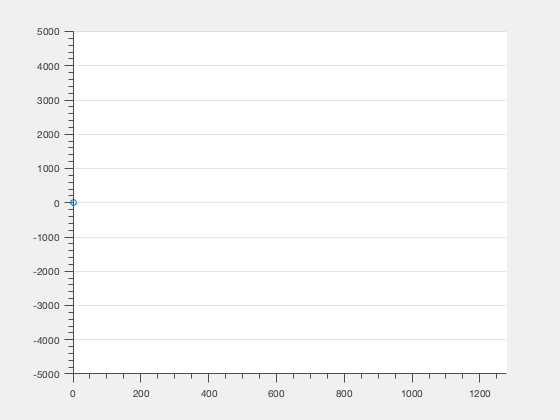

figure(1)

set(gcf,'Visible','on')

datareceivedchan=0;
t = 0;
h_plot=plot(t, datareceivedchan);

set(h_plot, ...
      'LineWidth'       , 1           , ...
      'Marker'          , 'o'         , ...
      'MarkerSize'      , 6)

set(gca, ...
  'Box'         , 'off'     , ...
  'TickDir'     , 'out'     , ...
  'TickLength'  , [.02 .02] , ...
  'XMinorTick'  , 'on'      , ...
  'YMinorTick'  , 'on'      , ...
  'YGrid'       , 'on'      , ...
  'XColor'      , [.3 .3 .3], ...
  'YColor'      , [.3 .3 .3], ...
  'XLim'        , [0,numberpoints],...
  'YLim'        , [-5000,5000],...
  'LineWidth'   , 1         );

Let's go!

% while receiveing data, continue.
while 1
    
    % while receiveing datapoint, continue.
    bytearrayread=client.readmessage(datapoint_size);
    
    
    if (sum(bytearrayread)==0)
       % datapoint complete.
        break;
    end
    
    if ~isempty(bytearrayread)
        t=t+1
        t2(t)=toc(t1);
        
        % read datapoint.
        datapoint_byte{t}=bytearrayread;
        % cast to appropriate class.
        datapoints(t,:)=typecast(datapoint_byte{t}, 'double');
       
        
        
        % size(datapoint)
        
        % update plot fro chan 1.
        datareceivedchan(t)=datapoints(t,1);
        
        set(h_plot, 'XData',1:t, 'YData', datareceivedchan);
        
        
    
        % start cleaning after initial window.
        
        % removing outliers.
        
        if t>windowsize
            
            
            for ch=1:numberchans
                
                % outlier detection.
                datasegment(:,ch)=datapoints(t-windowsize:t,ch);
                
                % compute sliding window mean.
                m_data=mean(datasegment);
                std_data=std(datasegment);
            
                outliers_idxs=find(abs(m_data-datasegment)>outlcoef*std_data);
                if(~isempty(outliers_idxs))
                    fprintf('found outliers in ch %i, idx %i \n', ch, t)
                end
                
                for i =1:length(outliers_idxs)
                    if datasegment(outliers_idxs(i)) > m_data
                        datasegment(outliers_idxs(i))=m_data+std_data*2.5;
                    else
                        datasegment(outliers_idxs(i))=m_data-std_data*2.5;
                    end
                end
                
                
                % low pass filter - moving average of x samples (pr channel)
                datasegmentcleaned(:,ch)=movmean(datasegment,movingavwindow)
            end
            
        end


        
        % Classifier
        
        % input vector - [40,1]
        % output - [1,1] label
        
        % output= trainedmodel(input) 
        
        
        
        % interface
        
        % if label==1
        %   present fig1
        % elseif label==2
        %   present fig2
        % else
        %   present fig3
        % end
    
        
        
    end   

end

Error using Eneeb_client/readmessage (line 80)
Java exception occurred: 
java.io.IOException: Stream closed.
	at java.net.AbstractPlainSocketImpl.available(AbstractPlainSocketImpl.java:470)
	at java.net.SocketInputStream.available(SocketInputStream.java:259)



client.close()

